% D section
% clc
% clear all
% close all

data=[
% 0.00011160714285713856, 0.0013422818791946345
% 0.0021205357142857102, 0.007382550335570476
0.00479910714285714, 0.012080536912751655
0.011495535714285712, 0.01610738255033556
0.017522321428571425, 0.01946308724832213
0.02287946428571428, 0.0221476510067114
0.029575892857142856, 0.025503355704698
0.036272321428571425, 0.028859060402684572
0.04564732142857143, 0.03288590604026845
0.05435267857142857, 0.03557046979865772
0.06238839285714286, 0.038255033557046986
0.07310267857142858, 0.040939597315436255
0.07979910714285714, 0.04228187919463089
0.08783482142857144, 0.04429530201342281
0.09854910714285714, 0.046308724832214765
0.10926339285714287, 0.048993288590604034
0.1166294642857143, 0.04966442953020135
0.12332589285714285, 0.05167785234899329
0.1306919642857143, 0.05302013422818792
0.13671875000000003, 0.055033557046979875
0.1481026785714286, 0.05704697986577183
0.1588169642857143, 0.059060402684563765
0.16752232142857143, 0.061073825503355716
0.17890625000000002, 0.06241610738255035
0.18627232142857145, 0.06375838926174499]

data =     0.0048    0.0121
    0.0115    0.0161
    0.0175    0.0195
    0.0229    0.0221
    0.0296    0.0255
    0.0363    0.0289
    0.0456    0.0329
    0.0544    0.0356
    0.0624    0.0383
    0.0731    0.0409


% 0.19363839285714288, 0.0651006711409396
% 0.20033482142857142, 0.06577181208053692]

hold on
plot(data(:,1),data(:,2))

Pol=polyfit(data(:,1),data(:,2),2)

Pol =    -0.9629    0.4479    0.0124


x=0:0.01:0.2

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000


y=polyval(Pol,x)

y =     0.0124    0.0168    0.0209    0.0249    0.0288    0.0324    0.0358    0.0390    0.0420    0.0449    0.0475    0.0500    0.0523    0.0543    0.0562    0.0579    0.0594    0.0607    0.0618    0.0627    0.0634


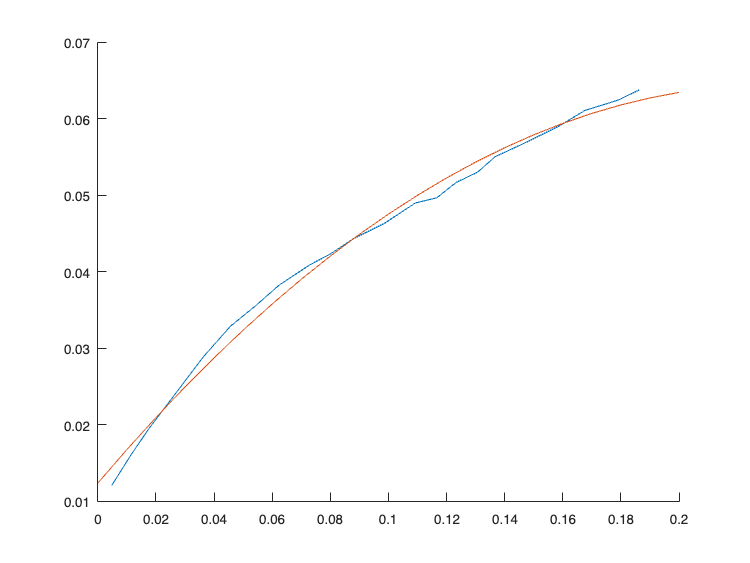

plot(x,y)


sym=poly2sym(Pol)

$$sym = -\frac{271023281116661\,x^{2}}{281474976710656}+\frac{1008623282072125\,x}{2251799813685248}+\frac{7133391534450547}{576460752303423488}$$


diff1=diff(sym)

$$diff1 = \frac{1008623282072125}{2251799813685248}-\frac{271023281116661\,x}{140737488355328}$$

diff2=diff(diff1)

$$diff2 = -\frac{271023281116661}{140737488355328}$$


% rad=10
% r=0:0.01:0.2
% for i=1:length(r)
%     A=subs(diff1,r(i));
%     B=subs(diff2,r(i));
%     Rad = double(((1+A^2)^(1.5))/abs(B));
%     if Rad<rad
%         rad=Rad;
%     end
% end

% Remi to provide Rib coordinates - RUN PROCESSREMIGRAPHS!!!
% rib_coordinates = rib.distL(1,:)
% % Rohan to determine chord and R

A=subs(diff1,0.1);
B=subs(diff2,0.1);
R1 = double(((1+A^2)^(1.5))/abs(B));

root_chord=4.073949602;
tip_chord=1.756951274;
span=12.165;

R =     2.3258    2.2995    2.2743    2.2500    2.2264    2.2035    2.1812    2.1593    2.1379    2.1169    2.0962    2.0759    2.0559    2.0361    2.0166    1.9974    1.9784    1.9595    1.9407    1.9220    1.9033    1.8846    1.8660    1.8474    1.8287    1.8101    1.7915    1.7728    1.7542    1.7354    1.7166    1.6978    1.6788    1.6598    1.6407    1.6215    1.6021    1.5825    1.5628    1.5429    1.5228    1.5025    1.4819    1.4609    1.4396    1.4179    1.3958    1.3732    1.3500    1.3261



% D-cell span length
% rib_spacing = rib.distL(2,:)

% t to be thickness of skin at each rib
% t=[]
% t(1:3)=4.19e-3;
% t(4:7)=4.45e-3
% t(8:14)=4.71e-3
% t(15:24)=4.76e-3
% t(25:32)=4.65e-3
% t(33:39)=4.43e-3
% t(40:45)=4.11e-3
% t(46:49)=3.73e-3
% t(50:52)=3.32e-3
% t(53:54)=2.89e-3
% t(55)=2.45e-3
% t(56)=2.23e-3
% t(57)=1.86e-3
% t(58)=1.41e-3
% t(59)=1e-3

% Find K at each point


% Implement pseudo ribs across the semi-span
wingbox_span = 12.165;
no_pseudo_ribs = 10;
a=wingbox_span/(no_pseudo_ribs+1)

a = 1.1059


coords=0:wingbox_span/(no_pseudo_ribs-1):wingbox_span

c = ((tip_chord-root_chord)/span).*rib_coordinates + root_chord;
R = R1.*c

b=0.2.*c;

t=[]


t =

     []



for i=1:no_pseudo_ribs
    t(i)=0.001
end

t = 1.0000e-03

t = 1.0e-03 *

    1.0000    1.0000


t = 1.0e-03 *

    1.0000    1.0000    1.0000


t = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000


t = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000


t = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


t = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


t = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


t = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


t = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



% a=rib_spacing;

a_over_b = a./b;
b_over_a = b./a;
denom=(R.*t).^(1/2)

Arrays have incompatible sizes for this operation.

Related documentation


K=[];

for i=1:length(a_over_b)
    if a_over_b(i) > 1
        K(i)=DBuckCoef(b(i)/denom(i),a_over_b(i))
    else
        K(i)=DBuckCoefb(a(i)/denom(i),b_over_a(i))
    end
end

% Check Tresca for each section 
S_y=310*10^6;
T_tresca = S_y/2;
%Al_2024
E=73.85*10^9;

T_crit = K.*E.*(t./b).^2;
T_F=[]
for i=1:length(T_crit)
    T_F(i) = T_crit(i) > T_tresca
end